% Load YALMIP
addpath(genpath('C:\Users\Lu34\OneDrive\Desktop\Year 4 Project II\Matlab simulation\acn_data\final codes\YALMIP-master')); % Add path
yalmip('clear')
load profiles.mat
% 
% Make sure to replace 'path_to_python' with the actual path to your Python executable
% pyversion('C:\Users\Lu34\AppData\Local\Programs\Python\Python310\python.exe');

% Specify the path to the CSV file
csvFilePath = 'C:\Users\Lu34\OneDrive\Desktop\Year 4 Project II\Matlab simulation\acn_data\final codes\combined_hourly_csv.csv';

opts = detectImportOptions(csvFilePath);
opts.VariableNamingRule = 'preserve';

% Read the CSV file into a table in MATLAB
dataTable = readtable(csvFilePath, opts);

% Display the table
disp(dataTable);

           Hour            Location1_kWh         Location2_kWh              Location3_kWh         Total_kWh
    ___________________    _____________    _______________________    _______________________    _________

                    NaT           NaN       {'kWhDeliveredPerHour'}    {'kWhDeliveredPerHour'}         NaN 
    2018-04-25 11:00:00         2.644       {0×0 char             }    {0×0 char             }       2.644 
    2018-04-25 12:00:00         2.644       {0×0 char             }    {0×0 char             }       2.644 
    2018-04-25 13:00:00        1.3188       {0×0 char             }    {0×0 char             }      1.3188 
    2018-04-25 14:00:00        1.2953       {0×0 char             }    {0×0 char             }      1.2953 
    2018-04-25 15:00:00       0.76793       {0×0 char             }    {0

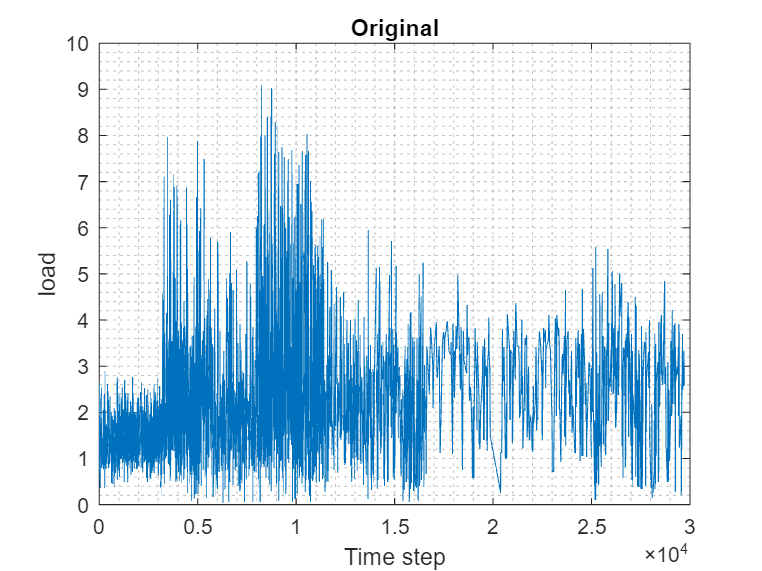


% Extract the second column
data = dataTable.Total_kWh(2:end); 

% Interpolate NaN values using linear interpolation
data = fillmissing(data, 'linear');


% data = load;

% Continue with the rest of your MATLAB script using the loaded 'data'
figure;
plot(data);
xlabel("Time step");
ylabel("load");
title("Original");
grid minor;



% Split the data into training, validation, and test sets
numObservations = numel(data);
numTimeStepsTrain = floor(0.8*numel(data)); % Adjust the split ratio as needed
numTimeStepsValidation = floor(0.1*numel(data));

idxTrain = 1:numTimeStepsTrain;
idxValidation = numTimeStepsTrain+1:numTimeStepsTrain+numTimeStepsValidation;
idxTest = numTimeStepsTrain+numTimeStepsValidation+1:numObservations;

dataTrain = data(idxTrain);
dataValidation = data(idxValidation);
dataTest = data(idxTest);

% Standardize the data
mu = mean(dataTrain);
sig = std(dataTrain);
mu_1 = mean(dataValidation);
sig_1 = std(dataValidation);
mu_2 = mean(dataTest);
sig_2 = std(dataTest);
mu_3 = mean(data);
sig_3 = std(data);

dataTrainStandardized = (dataTrain - mu) / sig;
dataValidationStandardized = (dataValidation - mu_1) / sig_1;
dataTestStandardized = (dataTest - mu_2) / sig_2;


% Define parameters
P = 32; % Number of past values to consider
F = 6; % Number of future values to predict

% Prepare input-output pairs for training, validation, and test sets
XTrain = [];
YTrain = [];
XValidation = [];
YValidation = [];
XTest = [];
YTest = [];

% Generate training sets
for k = P+1:length(dataTrainStandardized)-F
    XTrain(k-P,:) = dataTrainStandardized(k-P:k-1);
    YTrain(k-P,:) = dataTrainStandardized(k:k+F-1);
end

% Generate validation sets
for k = P+1:length(dataValidationStandardized)-F
    XValidation(k-P,:) = dataValidationStandardized(k-P:k-1);
    YValidation(k-P,:) = dataValidationStandardized(k:k+F-1);
end

% Generate test sets
for k = P+1:length(dataTestStandardized)-F
    XTest(k-P,:) = dataTestStandardized(k-P:k-1);
    YTest(k-P,:) = dataTestStandardized(k:k+F-1);
end

% Reshape
XTrain = XTrain';
YTrain = YTrain';
XValidation = XValidation';
YValidation = YValidation';
XTest = XTest';
YTest = YTest';

display(XTrain)

XTrain =     0.2733    0.2733   -0.8640   -0.8841   -1.3367   -1.1281   -1.1420   -1.1608   -1.0799   -1.1430   -1.1111   -1.0834   -1.0942   -1.0546   -0.9515   -0.6035   -0.4892   -0.3592   -0.5502   -1.4908   -1.5270   -1.5270   -1.5270   -1.5270   -1.2232   -1.2232   -1.1393   -1.3108   -1.4080   -1.2146   -1.1550   -1.1561   -1.1725   -1.2311   -1.2302   -1.2302   -1.2176   -1.2092   -1.0057   -0.7082   -0.6427   -0.4842   -1.2668   -1.6810   -1.6810   -1.6810   -1.6810   -1.6810   -1.6073   -1.6073
    0.2733   -0.8640   -0.8841   -1.3367   -1.1281   -1.1420   -1.1608   -1.0799   -1.1430   -1.1111   -1.0834   -1.0942   -1.0546   -0.9515   -0.6035   -0.4892   -0.3592   -0.5502   -1.4908   -1.5270   -1.5270   -1.5270   -1.5270   -1.2232   -1.2232   -1.1393   -1.3108   -1.4080   -1.2146   -1.1550   -1.1561   -1.1725   -1.2311   -1.2302   -1.2302   -1.2176   -1.2092   -1.0057   -0.7082   -0.6427   -0.4842   -1.2668   -1.6810   -1.6810   -1.6810   -1.6810   -1.6810   -1.6073   -1.6073

display(YTrain)

YTrain =    -1.1725   -1.2311   -1.2302   -1.2302   -1.2176   -1.2092   -1.0057   -0.7082   -0.6427   -0.4842   -1.2668   -1.6810   -1.6810   -1.6810   -1.6810   -1.6810   -1.6073   -1.6073   -1.5175   -1.0770   -1.0341   -0.8851   -0.8730   -0.9486   -0.9073   -0.9279   -0.8716   -0.8100   -0.8434   -0.7941   -0.5648   -0.7275   -0.6382   -0.5885   -0.5070   -0.6692   -0.7908   -0.7908   -0.7908   -0.8949   -0.8949   -0.8375   -0.7574   -0.5852   -0.5467   -0.5910   -0.1285   -0.1224   -0.1165   -0.0203
   -1.2311   -1.2302   -1.2302   -1.2176   -1.2092   -1.0057   -0.7082   -0.6427   -0.4842   -1.2668   -1.6810   -1.6810   -1.6810   -1.6810   -1.6810   -1.6073   -1.6073   -1.5175   -1.0770   -1.0341   -0.8851   -0.8730   -0.9486   -0.9073   -0.9279   -0.8716   -0.8100   -0.8434   -0.7941   -0.5648   -0.7275   -0.6382   -0.5885   -0.5070   -0.6692   -0.7908   -0.7908   -0.7908   -0.8949   -0.8949   -0.8375   -0.7574   -0.5852   -0.5467   -0.5910   -0.1285   -0.1224   -0.1165   -0.0203

display(XValidation)

XValidation =     1.0005    1.0034    1.0062    1.0091    1.0119    1.0148    1.0176    1.0205    1.0233    1.0262    1.0290    1.0319    1.0347    1.0376    1.0404    1.0433    1.0461    1.0489    1.0518    1.0546    1.0575    1.0603    1.0632    1.0660    1.0689    1.0717    1.0746    1.0774    1.0803    1.0831    1.0860    1.0888    1.0917    1.0945    1.0973    1.1002    1.1030    1.1059    1.1087    1.1116    1.1144    1.1173    1.1201    1.1230    1.1258    1.1287    1.1315    1.1344    1.1372    1.1401
    1.0034    1.0062    1.0091    1.0119    1.0148    1.0176    1.0205    1.0233    1.0262    1.0290    1.0319    1.0347    1.0376    1.0404    1.0433    1.0461    1.0489    1.0518    1.0546    1.0575    1.0603    1.0632    1.0660    1.0689    1.0717    1.0746    1.0774    1.0803    1.0831    1.0860    1.0888    1.0917    1.0945    1.0973    1.1002    1.1030    1.1059    1.1087    1.1116    1.1144    1.1173    1.1201    1.1230    1.1258    1.1287    1.1315    1.1344    1.1372    1

display(YValidation)

YValidation =     1.0917    1.0945    1.0973    1.1002    1.1030    1.1059    1.1087    1.1116    1.1144    1.1173    1.1201    1.1230    1.1258    1.1287    1.1315    1.1344    1.1372    1.1401    1.1401    1.1401    1.1401    1.1401    1.1401    0.3564    0.3564    0.3564    0.3564    0.3564    0.3317    0.3070    0.2822    0.2575    0.2328    0.2080    0.1833    0.1586    0.1339    0.1091    0.0844    0.0597    0.0349    0.0102   -0.0145   -0.0393   -0.0640   -0.0887   -0.1134   -0.1382   -0.1629   -0.1629
    1.0945    1.0973    1.1002    1.1030    1.1059    1.1087    1.1116    1.1144    1.1173    1.1201    1.1230    1.1258    1.1287    1.1315    1.1344    1.1372    1.1401    1.1401    1.1401    1.1401    1.1401    1.1401    0.3564    0.3564    0.3564    0.3564    0.3564    0.3317    0.3070    0.2822    0.2575    0.2328    0.2080    0.1833    0.1586    0.1339    0.1091    0.0844    0.0597    0.0349    0.0102   -0.0145   -0.0393   -0.0640   -0.0887   -0.1134   -0.1382   -0.1629   -0

display(XTest)

XTest =    -0.9884   -0.9145   -0.8406   -0.7667   -0.6928   -0.6189   -0.5450   -0.4711   -0.3972   -0.3233   -0.2494   -0.1755   -0.1016   -0.0277    0.0462    0.1201    0.1940    0.2679    0.3419    0.4158    0.4897    0.5636    0.6375    0.7114    0.7853    0.8592    0.9331    1.0070    1.0809    1.1548    1.2287    1.3026    1.3026    1.3026    1.1191    1.1191    1.1191    1.1191    1.1191    1.1191    1.1191    1.1114    1.1036    1.0959    1.0881    1.0803    1.0726    1.0648    1.0570    1.0493
   -0.9145   -0.8406   -0.7667   -0.6928   -0.6189   -0.5450   -0.4711   -0.3972   -0.3233   -0.2494   -0.1755   -0.1016   -0.0277    0.0462    0.1201    0.1940    0.2679    0.3419    0.4158    0.4897    0.5636    0.6375    0.7114    0.7853    0.8592    0.9331    1.0070    1.0809    1.1548    1.2287    1.3026    1.3026    1.3026    1.1191    1.1191    1.1191    1.1191    1.1191    1.1191    1.1191    1.1114    1.1036    1.0959    1.0881    1.0803    1.0726    1.0648    1.0570    1.0493 

display(YTest)

YTest =     1.3026    1.3026    1.1191    1.1191    1.1191    1.1191    1.1191    1.1191    1.1191    1.1114    1.1036    1.0959    1.0881    1.0803    1.0726    1.0648    1.0570    1.0493    1.0415    1.0338    1.0260    1.0182    1.0105    1.0027    0.9950    0.9872    0.9794    0.9717    0.9639    0.9561    0.9484    0.9406    0.9329    0.9251    0.9173    0.9096    0.9018    0.8940    0.8863    0.8785    0.8708    0.8630    0.8552    0.8475    0.8397    0.8320    0.8242    0.8164    0.8164    0.8164
    1.3026    1.1191    1.1191    1.1191    1.1191    1.1191    1.1191    1.1191    1.1114    1.1036    1.0959    1.0881    1.0803    1.0726    1.0648    1.0570    1.0493    1.0415    1.0338    1.0260    1.0182    1.0105    1.0027    0.9950    0.9872    0.9794    0.9717    0.9639    0.9561    0.9484    0.9406    0.9329    0.9251    0.9173    0.9096    0.9018    0.8940    0.8863    0.8785    0.8708    0.8630    0.8552    0.8475    0.8397    0.8320    0.8242    0.8164    0.8164    0.8164 

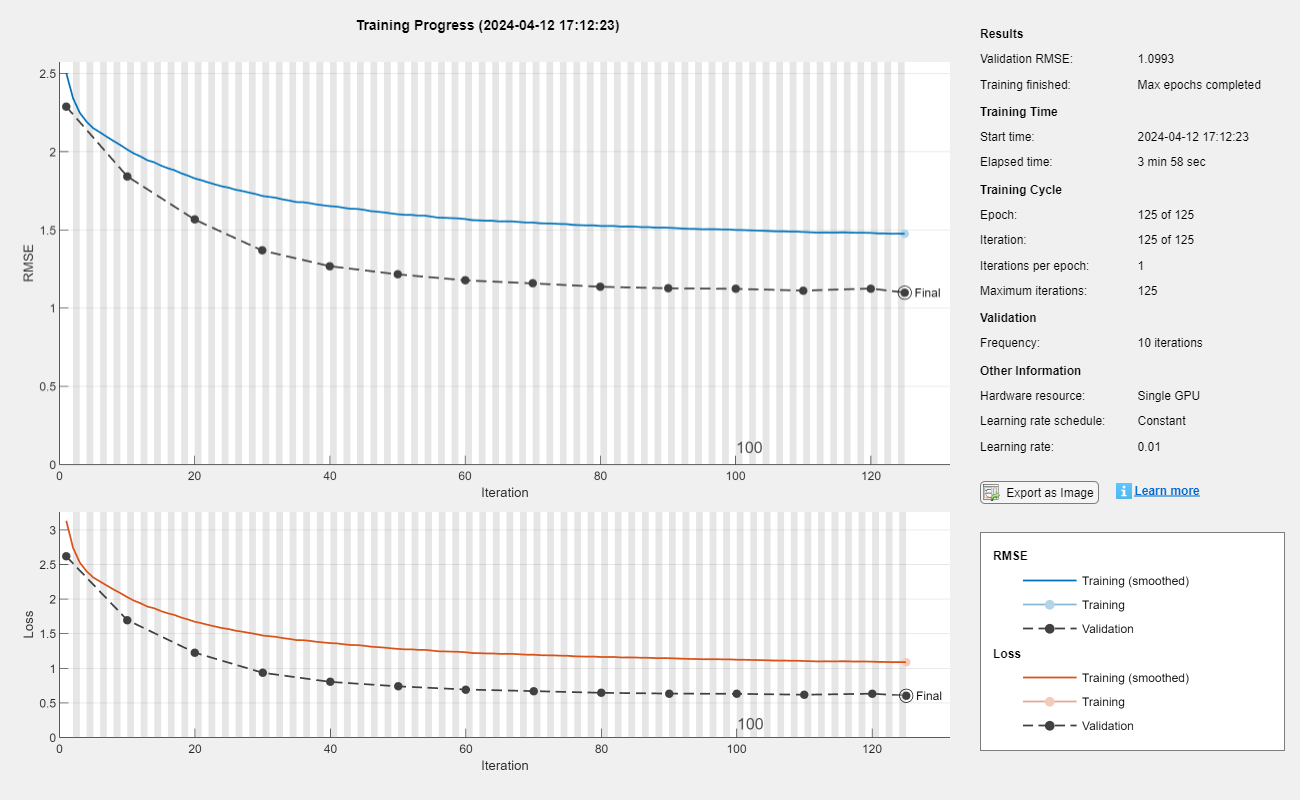

Hyperparameters: Hidden Units=12, Epochs=125, MiniBatchSize=128


Validation RMSE: 1.099342


-------------------------



% Create LSTM model

% layers = [
%     sequenceInputLayer(P, 'Name', 'input')
%     lstmLayer(numHiddenUnits, 'Name', 'lstm')
%     fullyConnectedLayer(F, 'Name', 'fc')
%     regressionLayer('Name', 'output')
% ];

% layers = [
%     sequenceInputLayer(P, 'Name', 'input')
%     lstmLayer(numHiddenUnits, 'Name', 'lstm1', 'OutputMode', 'sequence')
%     dropoutLayer(0.2, 'Name', 'dropout1')  % Optional: Dropout layer for regularization
%     lstmLayer(numHiddenUnits, 'Name', 'lstm2', 'OutputMode', 'sequence')
%     fullyConnectedLayer(64, 'Name', 'fc1')
%     reluLayer('Name', 'relu1')')
%     regressionLayer('Name', 'output')
% ];


% Define different values for hyperparameters
numHiddenUnitsList = 12;  % Add more values as needed, normally [12,24,32,48]
maxEpochsList = 125;  % Add more values as needed, normally [75,125,175]
miniBatchSizeList = 128;  % Add more values as needed, normally [32 64 128]

% Define variables to store the best hyperparameters and minimum validation RMSE
bestNumHiddenUnits = 0;
bestMaxEpochs = 0;
bestMiniBatchSize = 0;
minValidationRMSE = inf;

% Create a loop to iterate over hyperparameter values
for numHiddenUnits = numHiddenUnitsList
    for maxEpochs = maxEpochsList
        for miniBatchSize = miniBatchSizeList

            % Create or modify the layers and options based on the hyperparameters
            layers = [
                sequenceInputLayer(P, 'Name', 'input')
                lstmLayer(numHiddenUnits, 'Name', 'lstm', 'OutputMode', 'sequence')
                dropoutLayer(0.2, 'Name', 'dropout')  % Add a dropout layer
                fullyConnectedLayer(F, 'Name', 'fc')
                regressionLayer('Name', 'output')
            ];

            options = trainingOptions("adam", ...
                'MaxEpochs', maxEpochs, ...
                'MiniBatchSize', miniBatchSize, ...
                'SequencePaddingDirection', 'right', ...
                'SequenceLength', 'longest', ...
                'Shuffle', 'every-epoch', ...
                'InitialLearnRate', 0.01, ...
                'LearnRateDropFactor', 0.7, ...
                'LearnRateDropPeriod', 25, ...
                'Plots', 'training-progress', ...
                'Verbose', false, ...
                'ValidationData', {XValidation, YValidation}, ...
                'ValidationFrequency',10, ...
                'L2Regularization', 0.005);

                % 'GradientThreshold', 1, ...
                % 'InitialLearnRate', 0.01, ...
                % 'LearnRateDropFactor', 0.9, ...
                % 'LearnRateDropPeriod', 10, ...
                % 'LearnRateSchedule', 'piecewise', ..

                % 'InitialLearnRate', 0.01, ...
                % 'LearnRateDropFactor', 0.9, ...
                % 'LearnRateDropPeriod', 10, ...

            % Train the LSTM model
            [model, info] = trainNetwork(XTrain, YTrain, layers, options);

            % Extract the validation RMSE from the training progress
            validationRMSE = info.ValidationRMSE(end);

            % Compare with the minimum validation RMSE
            if validationRMSE < minValidationRMSE
                minValidationRMSE = validationRMSE;
                bestNumHiddenUnits = numHiddenUnits;
                bestMaxEpochs = maxEpochs;
                bestMiniBatchSize = miniBatchSize;
            end

            % Display or store results, such as RMSE, for each hyperparameter combination
            fprintf('Hyperparameters: Hidden Units=%d, Epochs=%d, MiniBatchSize=%d\n', numHiddenUnits, maxEpochs, miniBatchSize);
            fprintf('Validation RMSE: %f\n', validationRMSE);
            fprintf('-------------------------\n');
        end
    end
end



% Display the best hyperparameters and minimum validation RMSE
fprintf('Best Hyperparameters: Hidden Units=%d, Epochs=%d, MiniBatchSize=%d\n', bestNumHiddenUnits, bestMaxEpochs, bestMiniBatchSize);

Best Hyperparameters: Hidden Units=12, Epochs=125, MiniBatchSize=128


fprintf('Minimum Validation RMSE: %f\n', minValidationRMSE);

Minimum Validation RMSE: 1.099342


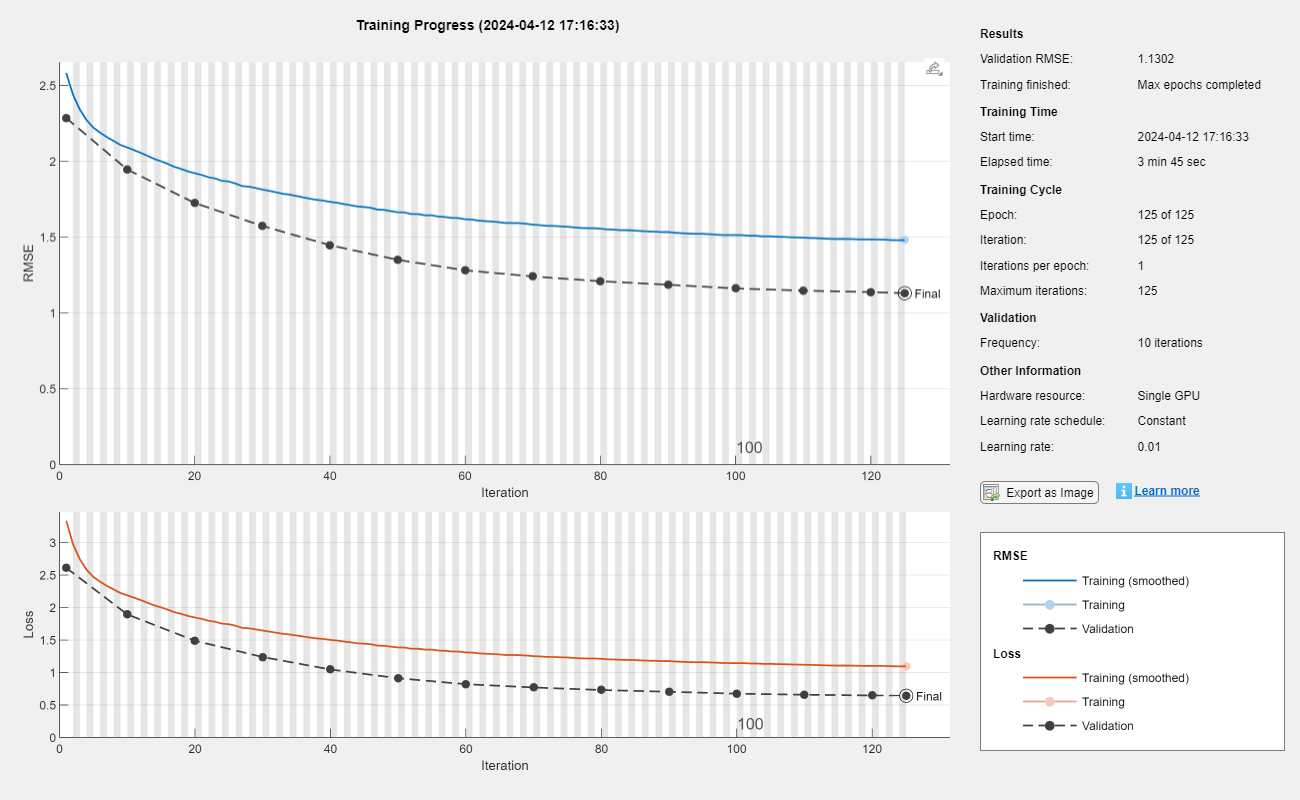


% Define the LSTM model architecture with the best hyperparameters
layers1 = [
    sequenceInputLayer(P, 'Name', 'input1')
    lstmLayer(bestNumHiddenUnits, 'Name', 'lstm1', 'OutputMode', 'sequence')
    dropoutLayer(0.2, 'Name', 'dropout1')  % Add a dropout layer
    fullyConnectedLayer(F, 'Name', 'fc1')
    regressionLayer('Name', 'output1')
    ];

options1 = trainingOptions("adam", ...
    'MaxEpochs', bestMaxEpochs, ...
    'MiniBatchSize', bestMiniBatchSize, ...
    'SequencePaddingDirection', 'right', ...
    'SequenceLength', 'longest', ...
    'Shuffle', 'every-epoch', ...
    'InitialLearnRate', 0.01, ...
    'LearnRateDropFactor', 0.7, ...
    'LearnRateDropPeriod', 25, ...
    'Plots', 'training-progress', ...
    'Verbose', false, ...
    'ValidationData', {XValidation, YValidation}, ...
    'ValidationFrequency',10, ...
    'L2Regularization', 0.005);


% Train the LSTM model
finalModel = trainNetwork(XTrain, YTrain, layers1, options1);


% Reset the model's state before making predictions
finalModel = resetState(finalModel);

% Add the testing and evaluation code here
SizeofXTest = size(XTest);
numXTest = SizeofXTest(2);
YPredicted_Test = zeros(F,numXTest); % Initialize the matrix to store predicted values zeros(F,numXTest)

for i = 1:numXTest
    % Extract the current input sequence
    currentSequence = XTest(:, i);

    % Reshape the input sequence to match the feature dimension of the model
    currentSequence = reshape(currentSequence, [P, 1, 1]);  % Reshape for LSTM input

    % Make a prediction for the next F time steps
    % Update YPredicted with the current prediction values
    currentPrediction = predict(finalModel, currentSequence, 'ExecutionEnvironment', 'cpu');  % Predict on GPU/CPU;

    % Update YPredicted with the current prediction values
    % Loop to fill each column of YPredicted
    for j = 1:F
        YPredicted_Test(j, i) = currentPrediction(j);
    end
end
% Display mean and standard deviation before destandardization
disp(['Before De-standardization: Mean(YTest): ' num2str(mean(YTest(:)))]);

Before De-standardization: Mean(YTest): -0.0031564


disp(['Std(YTest): ' num2str(std(YTest(:)))]);

Std(YTest): 1.0029



% De-standardize the predictions and testing output using the same mu and sig
YPredicted_Test = sig_2 .* YPredicted_Test + mu_2;
YTest = sig_2 .* YTest + mu_2;

% Display mean and standard deviation after destandardization
disp(['After De-standardization: Mean(YTest): ' num2str(mean(YTest(:)))]);

After De-standardization: Mean(YTest): 2.3303


disp(['Std(YTest): ' num2str(std(YTest(:)))]);

Std(YTest): 1.0563


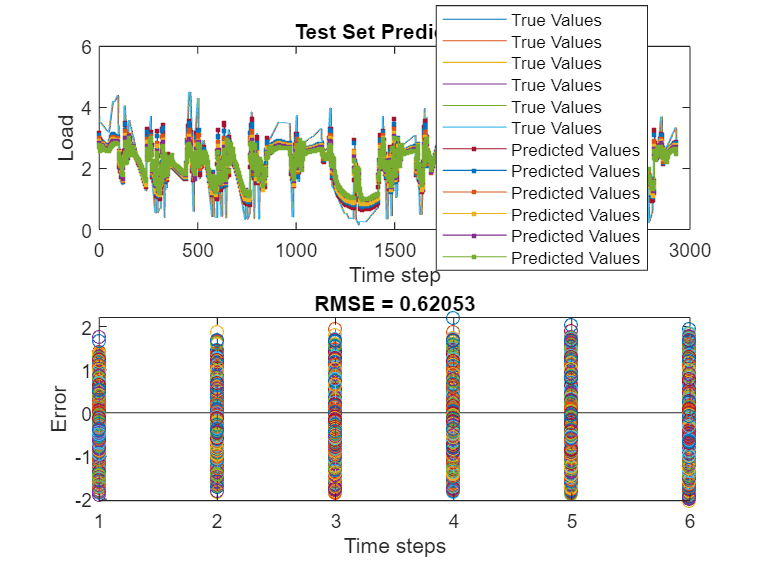


rmse = sqrt(mean((YPredicted_Test(:) - YTest(:)).^2));

% Visualize the results
figure;
subplot(2,1,1)
plot(1:length(YTest), YTest, '-','DisplayName', 'True Values');
hold on;
plot(1:length(YPredicted_Test), YPredicted_Test, '.-', 'DisplayName', 'Predicted Values');
xlabel("Time step");
ylabel("Load");
title("Test Set Predictions");
legend('Location', 'Best');
hold off;

subplot(2,1,2)
stem(YPredicted_Test - YTest)
xlabel("Time steps")
ylabel("Error")
title("RMSE = " + rmse)



YPredicted_Test_flatten = YPredicted_Test(1,:)

YPredicted_Test_flatten =     3.1827    3.1661    3.1360    2.9842    2.9477    2.9355    2.9533    2.9391    2.9198    2.9280    2.9209    2.8970    2.8848    2.8685    2.8676    2.8672    2.8648    2.8416    2.8548    2.8408    2.8456    2.8509    2.8285    2.8225    2.8033    2.7934    2.7750    2.7847    2.7648    2.7739    2.7600    2.7695    2.7537    2.7667    2.7618    2.7580    2.7548    2.7514    2.7485    2.7451    2.7423    2.7394    2.7365    2.7336    2.7307    2.7277    2.7247    2.7217    2.7186    2.7208


YTest_flatten = YTest(1,:)

YTest_flatten =     3.7056    3.7056    3.5123    3.5123    3.5123    3.5123    3.5123    3.5123    3.5123    3.5041    3.4960    3.4878    3.4796    3.4714    3.4633    3.4551    3.4469    3.4387    3.4306    3.4224    3.4142    3.4060    3.3979    3.3897    3.3815    3.3733    3.3652    3.3570    3.3488    3.3406    3.3325    3.3243    3.3161    3.3079    3.2998    3.2916    3.2834    3.2752    3.2671    3.2589    3.2507    3.2425    3.2344    3.2262    3.2180    3.2098    3.2017    3.1935    3.1935    3.1935


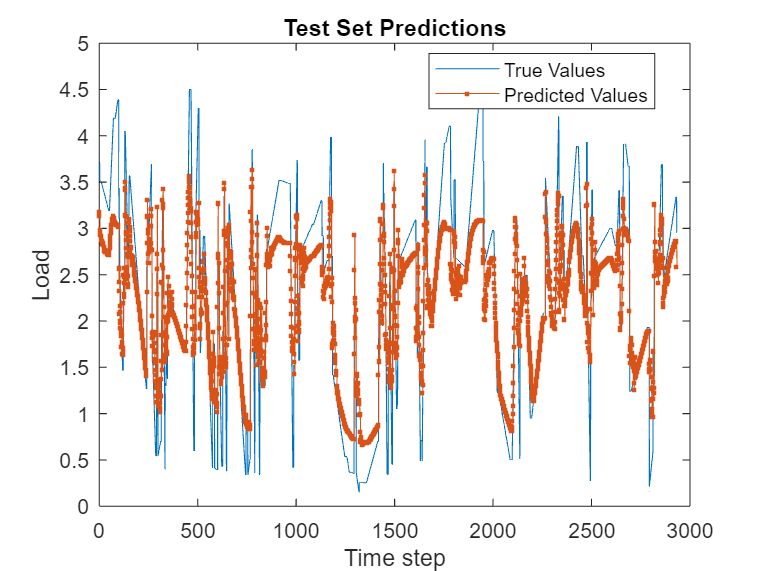


figure;
plot(1:length(YTest_flatten), YTest_flatten, '-','DisplayName', 'True Values');
hold on;
plot(1:length(YPredicted_Test_flatten), YPredicted_Test_flatten, '.-', 'DisplayName', 'Predicted Values');
xlabel("Time step");
ylabel("Load");
title("Test Set Predictions");
legend('Location', 'Best');
hold off;